# **Derive the equations of motion of a 4 wheel, 3-dof car model:**

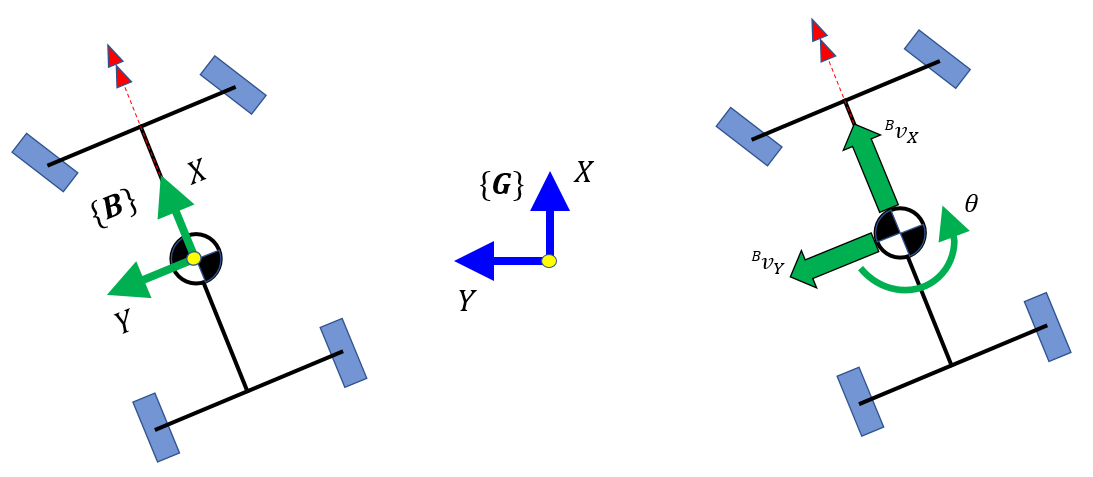

In this script we'll derive the equations of motion for a 4 wheel remote controlled car. Specifically we'll represent the car dynamics via 3 degrees of freedom.  Some highlights include:

- We'll start by defining Newton's 2nd law for a rigid body

- We'll use the Symbolic math toolbox to help us implement and manipulate Newton's laws.

- We'll automatically convert the derived equations of motion into Simulink blocks

` Bradley Horton : 27-Nov-2017, bradley.horton@mathworks.com.au`

## Equations of motion according to a body fixed frame:

Recall our fundamental equations of motion for a RIGID body - these equations are expressed in the body fixed vehicle {B}-frame:


$$^BF = m.(\enspace ^B_-\dot{v}_C  \enspace + \enspace
{^B_G\omega_B} \times {^B_Gv_C} \enspace)$$



$$^BM = {^BI} \thinspace . ^B_-\dot{\omega}_B  \enspace + \enspace
{^B_G\omega_B} \times ({^BI \thinspace. \thinspace ^B_G\omega_B}) \enspace$$


where:

- $\matrix{

 {^B_Gv_C}  
}$    :    A vector representing the vehicles ***velocity*** of the  centre of mass C.  The vector is expressed in components of the B-frame.  The G subscript indicates that the "measurement" of the velocity is as seen by the G-frame. 

- $\matrix{
 ^B_-\dot{v}_C = \enspace 
_B\pmatrix{
\frac{d \enspace ^B_Gv_C}{dt}
}
}$    :    the derivative of $^B_Gv_C$ as seen by the B-frame, and expressed in components of the B-frame.  So if we integrate $^B_-\dot{v}_C$, then we'll get $^B_Gv_C$.

- $\matrix{

 {^B_G\omega_B}  
}$   :    the angular ***velocity*** of the B-frame as observed by the G-frame, and expressed in components of the B-frame.

- $\matrix{
 {^B_-\dot{\omega}_B}  = \enspace

_B\pmatrix{
\frac{d \enspace ^B_G{\omega}_B}{dt}
}
}
}$   :    the derivative of  $\matrix{
{^B_G{\omega}_B}  
}$  as seen by the B-frame, and expressed in components of the B-frame.  So if we integrate $\matrix{

{^B_-\dot{\omega}_B}  
}$, then we'll get $\matrix{
{^B_G{\omega}_B}  
}$.

- $\matrix{

 {^BI}  
}$      :    the Inertia of the body computed about the B-frame which is attached to the body's center of mass.

-  *B-frame*  :    the body fixed frame attached to the body's center of mass.

-  G*-frame*  :   the inertial reference frame.

-  $A\text{ }\ldotp B$  :   matrix A multiplied by matrix B.

- $a\times \text{ }b$  :   vector cross product.

For our system, the degrees of freedom are:

- 
$$^B_Gv_{CX}$$


- 
$$^B_Gv_{CY}$$


- 
$$\theta$$


## So let's explore our FORCE equation:

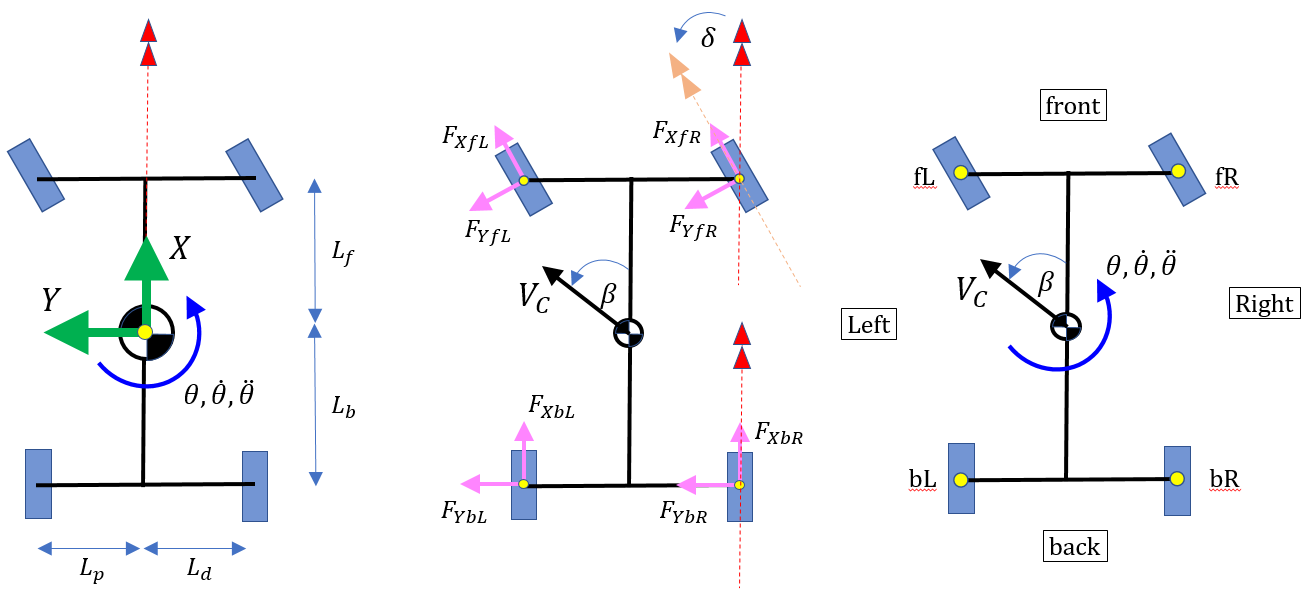

syms t theta(t) v_xB(t) v_yB(t) m

theta_dot = diff(theta(t), t);

w_B       = [       0,         0,   theta_dot  ].' ;
v_B       = [ v_xB(t),   v_yB(t),           0  ].';
v_B_dot   = diff(v_B, t);
w_B_dot   = diff(w_B, t);

So our FORCE equation becomes:     

- 
$$^BF = m.(\enspace ^B_-\dot{v}_C  \enspace + \enspace
{^B_G\omega_B} \times {^B_Gv_C} \enspace)$$


F_RHS = m*(v_B_dot + cross(w_B, v_B) )

$$F\_RHS = \left(\begin{array}{c} -m\,\left(v_{\mathrm{yB}}\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-\frac{\partial }{\partial t}v_{\mathrm{xB}}\left(t\right)\right)\\ m\,\left(v_{\mathrm{xB}}\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+\frac{\partial }{\partial t}v_{\mathrm{yB}}\left(t\right)\right)\\ 0 \end{array}\right)$$

If we focus on the XY plane we see that the FORCE equations for our car is:                                    

-   $\left\lbrack \begin{array}{c}
{}^B_{\text{ }}F^{\text{ }}_X\\
{}^B_{\text{ }}F^{\text{ }}_Y
\end{array}\right\rbrack$ =$\text{   }m\ldotp \left\lbrack \begin{array}{c}
{}^B_Ga^{\text{ }}_{\text{Cx}}\\
{}^B_Ga^{\text{ }}_{\text{Cy}}
\end{array}\right\rbrack \text{ }=\text{ }m\ldotp \left\lbrack \begin{array}{c}
{}^B_G{\dot{v} }^{\text{ }}_{\text{Cx}}\text{ }-\dot{\text{ }\theta } \ldotp {}^B_Gv^{\text{ }}_{\text{Cy}}\\
{}^B_G{\dot{v} }^{\text{ }}_{\text{Cy}}\text{ }\text{ }+\text{  }\dot{\text{ }\theta } \ldotp {}^B_Gv^{\text{ }}_{\text{Cx}}
\end{array}\right\rbrack$    ............. ***(1.)***

## Similarly let's consider our MOMENT equation:

syms I_xx I_xy I_xz I_yy I_yz I_zz

I       =  [ I_xx, I_xy, I_xz;
             I_xy, I_yy, I_yz;
             I_xz, I_yz, I_zz; ];

So our Moment equation becomes:

- 
$$^BM = {^BI} \thinspace . ^B_-\dot{\omega}_B  \enspace + \enspace
{^B_G\omega_B} \times ({^BI \thinspace. \thinspace ^B_G\omega_B}) \enspace$$


M_RHS     = I*w_B_dot + cross(w_B, I*w_B)

$$M\_RHS = \left(\begin{array}{c} I_{\mathrm{xz}}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)-I_{\mathrm{yz}}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ I_{\mathrm{yz}}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+I_{\mathrm{xz}}\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\\ I_{\mathrm{zz}}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right) \end{array}\right)$$

If we focus on the rotational motion about the Z-axis, we see that the TORQUE equation for our car is simply: 

-   $M_{\text{zB}} =I_{\mathrm{ZZ}} \text{ }\ldotp \theta^{¨} \text{ }$   ............. ***(2.)*** 

## Determine the Net Force and moments in vehicle body {B}-frame:

syms L_f  L_b  L_p  L_d
syms delta         % steering angle  

syms F_XfR F_YfR   % Front RIGHT tyre forces applied to car body
syms F_XfL F_YfL   % Front LEFT  tyre forces applied to car body

syms F_XbR F_YbR   % Back RIGHT tyre forces applied to car body
syms F_XbL F_YbL   % Back Left  tyre forces applied to car body

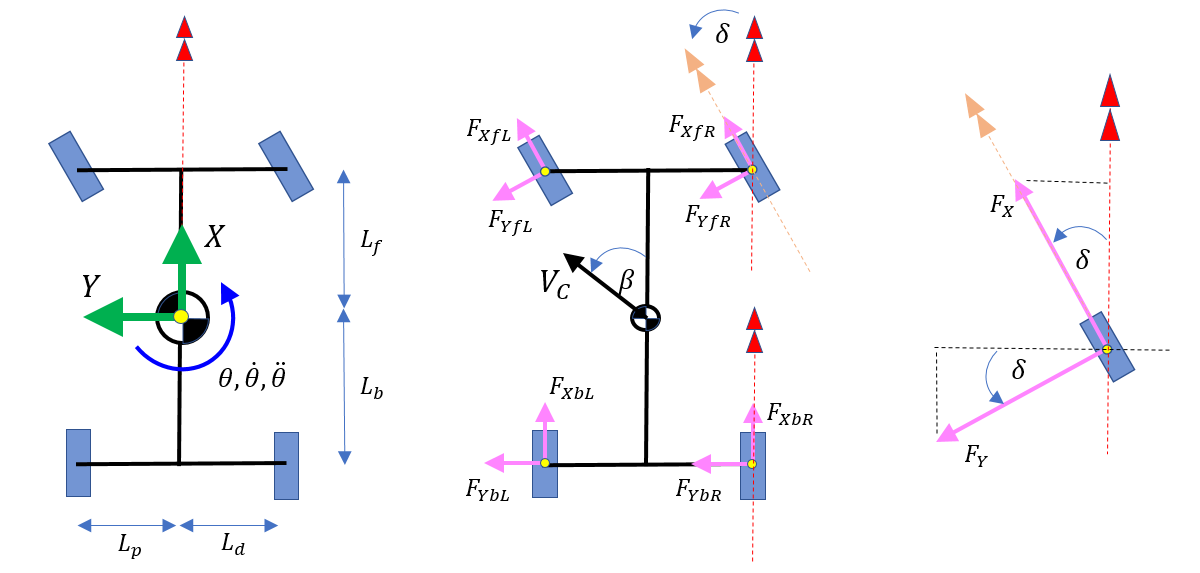

Let's define the X and Y force components at each wheel AND also the position of each wheel's centroid - we'll express these quantities in componentsof the** {B}-frame **attached to the car.

Cd = cos(delta);
Sd = sin(delta);

Note that the columns in the matrices below represent the wheels in the following order:

- 
$$\left\lbrack \begin{array}{cccc}
{\mathrm{FRONT}}_{\mathrm{Right}}  & {\mathrm{FRONT}}_{\mathrm{Left}}  & {\mathrm{BACK}}_{\mathrm{Right}}  & {\mathrm{BACK}}_{\mathrm{Left}} 
\end{array}\right\rbrack$$


So here are the Force and Position matrices  - expressed  in componentsof the** car's {B}-frame**

%                          #1_fR                    #2_fL          #3_bR     #4_bL
Fw_mat = [ (F_XfR*Cd - F_YfR*Sd),   (F_XfL*Cd - F_YfL*Sd),         F_XbR,    F_XbL;
           (F_XfR*Sd + F_YfR*Cd),   (F_XfL*Sd + F_YfL*Cd),         F_YbR,    F_YbL;
                               0,                       0,             0,        0;
         ];
%                          #1_fR                    #2_fL          #3_bR     #4_bL
Pw_mat = [                  L_f ,                     L_f,        (-L_b),   (-L_b);
                          (-L_d),                     L_p,        (-L_d),     L_p ;
                               0,                       0,             0,        0;
         ];
% and I'll write out a matrix to a Simulink block too:
Fb_mat_fR_fL_bR_bL = Fw_mat(1:2,:);

And now process:

F_X = 0;   F_Y = 0;  M_Z = 0;
for kk=1:4
   % accumulate the x and y components of Force 
   F_X =  F_X + Fw_mat(1,kk);
   F_Y =  F_Y + Fw_mat(2,kk);   
    
   tmp_F = Fw_mat(:,kk);
   tmp_r = Pw_mat(:,kk);
   
   % compute moment created by each force:  M = r x F
   tmp_M = cross(tmp_r, tmp_F);
   
   % accumulate the moments
   M_Z = M_Z + tmp_M(3);
end

and echo the results

F_X

$$F\_X = F_{\mathrm{XbL}}+F_{\mathrm{XbR}}+F_{\mathrm{XfL}}\,\cos\left(\delta \right)+F_{\mathrm{XfR}}\,\cos\left(\delta \right)-F_{\mathrm{YfL}}\,\sin\left(\delta \right)-F_{\mathrm{YfR}}\,\sin\left(\delta \right)$$

and

F_Y

$$F\_Y = F_{\mathrm{YbL}}+F_{\mathrm{YbR}}+F_{\mathrm{YfL}}\,\cos\left(\delta \right)+F_{\mathrm{YfR}}\,\cos\left(\delta \right)+F_{\mathrm{XfL}}\,\sin\left(\delta \right)+F_{\mathrm{XfR}}\,\sin\left(\delta \right)$$

and

M_Z

$$M\_Z = F_{\mathrm{XbR}}\,L_{d}-F_{\mathrm{YbR}}\,L_{b}-F_{\mathrm{YbL}}\,L_{b}-F_{\mathrm{XbL}}\,L_{p}+L_{d}\,\left(F_{\mathrm{XfR}}\,\cos\left(\delta \right)-F_{\mathrm{YfR}}\,\sin\left(\delta \right)\right)+L_{f}\,\left(F_{\mathrm{YfL}}\,\cos\left(\delta \right)+F_{\mathrm{XfL}}\,\sin\left(\delta \right)\right)+L_{f}\,\left(F_{\mathrm{YfR}}\,\cos\left(\delta \right)+F_{\mathrm{XfR}}\,\sin\left(\delta \right)\right)-L_{p}\,\left(F_{\mathrm{XfL}}\,\cos\left(\delta \right)-F_{\mathrm{YfL}}\,\sin\left(\delta \right)\right)$$

And also compute the velocities of each wheel centroid:     $v_W \text{ }={\text{ }v}_{\mathrm{car}} \text{ }\text{ }+\text{   }\omega \times r_W$

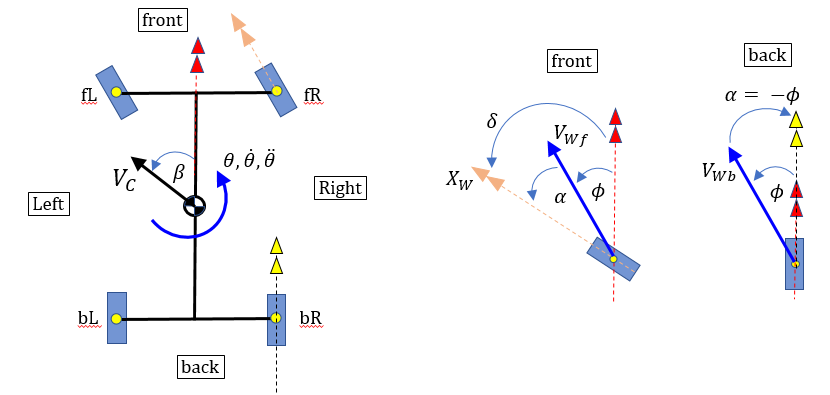

Vw_fR = v_B  +  cross(w_B, Pw_mat(:,1) )

$$Vw\_fR = \left(\begin{array}{c} L_{d}\,\frac{\partial }{\partial t}\theta \left(t\right)+v_{\mathrm{xB}}\left(t\right)\\ L_{f}\,\frac{\partial }{\partial t}\theta \left(t\right)+v_{\mathrm{yB}}\left(t\right)\\ 0 \end{array}\right)$$

Vw_fL = v_B  +  cross(w_B, Pw_mat(:,2) )

$$Vw\_fL = \left(\begin{array}{c} v_{\mathrm{xB}}\left(t\right)-L_{p}\,\frac{\partial }{\partial t}\theta \left(t\right)\\ L_{f}\,\frac{\partial }{\partial t}\theta \left(t\right)+v_{\mathrm{yB}}\left(t\right)\\ 0 \end{array}\right)$$

Vw_bR = v_B  +  cross(w_B, Pw_mat(:,3) )

$$Vw\_bR = \left(\begin{array}{c} L_{d}\,\frac{\partial }{\partial t}\theta \left(t\right)+v_{\mathrm{xB}}\left(t\right)\\ v_{\mathrm{yB}}\left(t\right)-L_{b}\,\frac{\partial }{\partial t}\theta \left(t\right)\\ 0 \end{array}\right)$$

Vw_bL = v_B  +  cross(w_B, Pw_mat(:,4) )

$$Vw\_bL = \left(\begin{array}{c} v_{\mathrm{xB}}\left(t\right)-L_{p}\,\frac{\partial }{\partial t}\theta \left(t\right)\\ v_{\mathrm{yB}}\left(t\right)-L_{b}\,\frac{\partial }{\partial t}\theta \left(t\right)\\ 0 \end{array}\right)$$

And just remove the Z component of the wheel velocity - (we don't need it):

Vw_fR(3) = []; 
Vw_fL(3) = [];   
Vw_bR(3) = [];  
Vw_bL(3) = []; 

## Define lateral slip angles for each wheel:

We'll define the lateral slip angle as the angle between the wheel's velocity vector and the wheel fixed X axis $^WX$ . Positive rotations are according to the right hand rule:

- **REF:  **[**Definition of Lateral tyre slip angle**](https://en.wikipedia.org/wiki/Slip_angle)

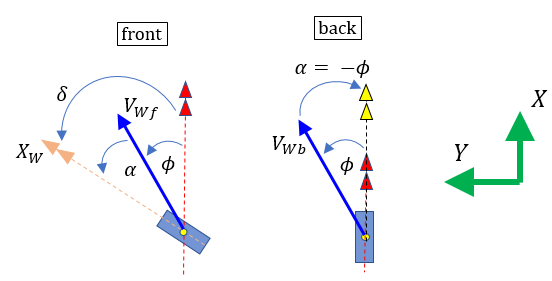

The FRONT wheel lateral slip angles:

% Y          X  
alpha_fR = delta - atan( Vw_fR(2) / Vw_fR(1) )

$$alpha\_fR = \delta -\mathrm{atan}\left(\frac{L_{f}\,\frac{\partial }{\partial t}\theta \left(t\right)+v_{\mathrm{yB}}\left(t\right)}{L_{d}\,\frac{\partial }{\partial t}\theta \left(t\right)+v_{\mathrm{xB}}\left(t\right)}\right)$$

alpha_fL = delta - atan( Vw_fL(2) / Vw_fL(1) )

$$alpha\_fL = \delta -\mathrm{atan}\left(\frac{L_{f}\,\frac{\partial }{\partial t}\theta \left(t\right)+v_{\mathrm{yB}}\left(t\right)}{v_{\mathrm{xB}}\left(t\right)-L_{p}\,\frac{\partial }{\partial t}\theta \left(t\right)}\right)$$

The BACK wheel lateral slip angles:

                          % Y          X  
alpha_bR =  -1 * atan( Vw_bR(2) / Vw_bR(1) )

$$alpha\_bR = -\mathrm{atan}\left(\frac{v_{\mathrm{yB}}\left(t\right)-L_{b}\,\frac{\partial }{\partial t}\theta \left(t\right)}{L_{d}\,\frac{\partial }{\partial t}\theta \left(t\right)+v_{\mathrm{xB}}\left(t\right)}\right)$$

alpha_bL =  -1 * atan( Vw_bL(2) / Vw_bL(1) )

$$alpha\_bL = -\mathrm{atan}\left(\frac{v_{\mathrm{yB}}\left(t\right)-L_{b}\,\frac{\partial }{\partial t}\theta \left(t\right)}{v_{\mathrm{xB}}\left(t\right)-L_{p}\,\frac{\partial }{\partial t}\theta \left(t\right)}\right)$$

## Define some new symbols :

syms THE_theta  THE_theta_D  THE_theta_DD
syms THE_v_xB   THE_v_xB_D  
syms THE_v_yB   THE_v_yB_D

ACTUAL_list = [theta(t),  diff(theta(t),t),  diff(theta(t),2),      v_xB(t),   diff(v_xB(t)),      v_yB(t),   diff(v_yB(t)) ];
HOLDER_list = [THE_theta,      THE_theta_D,      THE_theta_DD,  THE_v_xB,       THE_v_xB_D,    THE_v_yB,       THE_v_yB_D   ];

## Combine LHS and RHS of equations:

Combine the left and right hand sides of each equation:

F_X_EQN = F_X == F_RHS(1)

$$F\_X\_EQN = F_{\mathrm{XbL}}+F_{\mathrm{XbR}}+F_{\mathrm{XfL}}\,\cos\left(\delta \right)+F_{\mathrm{XfR}}\,\cos\left(\delta \right)-F_{\mathrm{YfL}}\,\sin\left(\delta \right)-F_{\mathrm{YfR}}\,\sin\left(\delta \right)=-m\,\left(v_{\mathrm{yB}}\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)-\frac{\partial }{\partial t}v_{\mathrm{xB}}\left(t\right)\right)$$

F_Y_EQN = F_Y == F_RHS(2)

$$F\_Y\_EQN = F_{\mathrm{YbL}}+F_{\mathrm{YbR}}+F_{\mathrm{YfL}}\,\cos\left(\delta \right)+F_{\mathrm{YfR}}\,\cos\left(\delta \right)+F_{\mathrm{XfL}}\,\sin\left(\delta \right)+F_{\mathrm{XfR}}\,\sin\left(\delta \right)=m\,\left(v_{\mathrm{xB}}\left(t\right)\,\frac{\partial }{\partial t}\theta \left(t\right)+\frac{\partial }{\partial t}v_{\mathrm{yB}}\left(t\right)\right)$$

M_Z_EQN = M_Z == M_RHS(3)

$$M\_Z\_EQN = F_{\mathrm{XbR}}\,L_{d}-F_{\mathrm{YbR}}\,L_{b}-F_{\mathrm{YbL}}\,L_{b}-F_{\mathrm{XbL}}\,L_{p}+L_{d}\,\left(F_{\mathrm{XfR}}\,\cos\left(\delta \right)-F_{\mathrm{YfR}}\,\sin\left(\delta \right)\right)+L_{f}\,\left(F_{\mathrm{YfL}}\,\cos\left(\delta \right)+F_{\mathrm{XfL}}\,\sin\left(\delta \right)\right)+L_{f}\,\left(F_{\mathrm{YfR}}\,\cos\left(\delta \right)+F_{\mathrm{XfR}}\,\sin\left(\delta \right)\right)-L_{p}\,\left(F_{\mathrm{XfL}}\,\cos\left(\delta \right)-F_{\mathrm{YfL}}\,\sin\left(\delta \right)\right)=I_{\mathrm{zz}}\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)$$

## Solve for ${\dot{v} }_{\mathrm{xb}} \text{ },{\dot{v} }_{\mathrm{yb}} \text{ },\text{ }\theta^{¨}$ :

Now populate with new symbols:

F_X_EQN = subs(F_X_EQN, ACTUAL_list, HOLDER_list);
F_Y_EQN = subs(F_Y_EQN, ACTUAL_list, HOLDER_list);
M_Z_EQN = subs(M_Z_EQN, ACTUAL_list, HOLDER_list);

Now solve:

my_sol = solve([F_X_EQN, F_Y_EQN, M_Z_EQN], [THE_v_xB_D, THE_v_yB_D, THE_theta_DD] )

my_sol = struct with fields:
      THE_v_xB_D: [1×1 sym]
      THE_v_yB_D: [1×1 sym]
    THE_theta_DD: [1×1 sym]


And you can echo the results if you want:

my_sol.THE_v_xB_D

$$ans = \frac{F_{\mathrm{XbL}}+F_{\mathrm{XbR}}+F_{\mathrm{XfL}}\,\cos\left(\delta \right)+F_{\mathrm{XfR}}\,\cos\left(\delta \right)-F_{\mathrm{YfL}}\,\sin\left(\delta \right)-F_{\mathrm{YfR}}\,\sin\left(\delta \right)+{\mathrm{THE}}_{v,\mathrm{yB}}\,{\mathrm{THE}}_{\theta ,D}\,m}{m}$$

and

my_sol.THE_v_yB_D

$$ans = \frac{F_{\mathrm{YbL}}+F_{\mathrm{YbR}}+F_{\mathrm{YfL}}\,\cos\left(\delta \right)+F_{\mathrm{YfR}}\,\cos\left(\delta \right)+F_{\mathrm{XfL}}\,\sin\left(\delta \right)+F_{\mathrm{XfR}}\,\sin\left(\delta \right)-{\mathrm{THE}}_{v,\mathrm{xB}}\,{\mathrm{THE}}_{\theta ,D}\,m}{m}$$

and

my_sol.THE_theta_DD

$$ans = \frac{F_{\mathrm{XbR}}\,L_{d}-F_{\mathrm{YbR}}\,L_{b}-F_{\mathrm{YbL}}\,L_{b}-F_{\mathrm{XbL}}\,L_{p}+F_{\mathrm{XfR}}\,L_{d}\,\cos\left(\delta \right)+F_{\mathrm{YfL}}\,L_{f}\,\cos\left(\delta \right)+F_{\mathrm{YfR}}\,L_{f}\,\cos\left(\delta \right)-F_{\mathrm{XfL}}\,L_{p}\,\cos\left(\delta \right)-F_{\mathrm{YfR}}\,L_{d}\,\sin\left(\delta \right)+F_{\mathrm{XfL}}\,L_{f}\,\sin\left(\delta \right)+F_{\mathrm{XfR}}\,L_{f}\,\sin\left(\delta \right)+F_{\mathrm{YfL}}\,L_{p}\,\sin\left(\delta \right)}{I_{\mathrm{zz}}}$$

## Convert expressions into HOLDER variables:

The slide slip angles:

alpha_fR = subs(alpha_fR, ACTUAL_list, HOLDER_list);
alpha_fL = subs(alpha_fL, ACTUAL_list, HOLDER_list);
alpha_bR = subs(alpha_bR, ACTUAL_list, HOLDER_list);
alpha_bL = subs(alpha_bL, ACTUAL_list, HOLDER_list);

The wheel velocities:

Vw_fR    = subs(Vw_fR, ACTUAL_list, HOLDER_list);
Vw_fL    = subs(Vw_fL, ACTUAL_list, HOLDER_list);
Vw_bR    = subs(Vw_bR, ACTUAL_list, HOLDER_list);
Vw_bL    = subs(Vw_bL, ACTUAL_list, HOLDER_list);

## Create Simulink blocks of our ${\dot{v} }_{\mathrm{xb}} \text{ },{\dot{v} }_{\mathrm{yb}} \text{ },\text{ }\theta^{¨}$ equations:

To use/solve these derived equations of motion we'll create a MATLAB Function block that can be used inside Simulink:

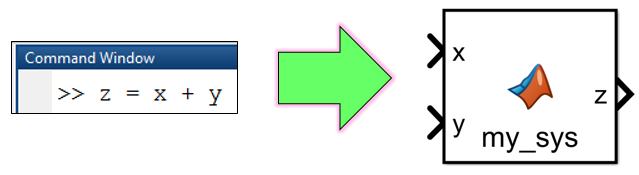

Now create the MATLAB function blocks for Simulink:

tf_i_should_create_SL_block = true;
if(true==tf_i_should_create_SL_block)
    MODEL_NAME = 'bh_tmp_model_for_3dof_car';

    if(4==exist(MODEL_NAME))
        close_system(MODEL_NAME, 0);
        delete(MODEL_NAME);
    end
    new_system(MODEL_NAME)
    open_system(MODEL_NAME)   

    % --------------------------------------------------------------------------------
    BLOCK_NAME = [MODEL_NAME,'/3DOF_EOM'];
    
    % specify the order of the signals for the input ports 
    vars_INPUTS = {m, I_zz,              ...
                   L_f,  L_b,  L_p,  L_d, ...
                   delta,         ...
                   F_XfR, F_YfR, ...   % Front RIGHT tyre forces
                   F_XfL, F_YfL, ...   % Front LEFT  tyre forces
                   F_XbR, F_YbR, ...   % Back RIGHT tyre forces
                   F_XbL, F_YbL, ...   % Back Left  tyre forces
                   THE_v_xB,     ...
                   THE_v_yB,     ...
                   THE_theta_D   ...
                   };
        
    % Put BOTH equations into one block 
    matlabFunctionBlock( BLOCK_NAME, ...
                          [my_sol.THE_v_xB_D; my_sol.THE_v_yB_D], ...
                          my_sol.THE_theta_DD,                    ...
                          [F_X; F_Y; M_Z],                        ...
                          Fb_mat_fR_fL_bR_bL,                     ...
                         'Optimize', false, ...
                         'Vars', vars_INPUTS, ...
                         'Outputs', {'vB_xy_D', 'theta_DD', 'FxyMz', 'Fb_mat_fR_fL_bR_bL'}   );  
                     
   % make the block YELLOW                   
   set_param( BLOCK_NAME,'BackgroundColor', '[0.996078, 1.000000, 0.705882]');     
    % --------------------------------------------------------------------------------   
   BLOCK_NAME = [MODEL_NAME,'/LAT_SLIP_ANGLES'];
    % specify the order of the signals for the input ports 
    vars_INPUTS = {L_f,  L_b,  L_p,  L_d, ...
                   delta,         ...
                   THE_v_xB,     ...
                   THE_v_yB,     ...
                   THE_theta_D   ...
                   };
        
    % Put BOTH equations into one block 
    matlabFunctionBlock( BLOCK_NAME, ...
                          alpha_fR, alpha_fL,  alpha_bR, alpha_bL, ...
                         'Optimize', false, ...
                         'Vars', vars_INPUTS, ...
                         'Outputs', {'alpha_fR', 'alpha_fL',  'alpha_bR', 'alpha_bL'}   );  
                     
   % make the block YELLOW                   
   set_param( BLOCK_NAME,'BackgroundColor', '[0.996078, 1.000000, 0.705882]');        
    % --------------------------------------------------------------------------------   
   BLOCK_NAME = [MODEL_NAME,'/WHEEL_VEL'];
    % specify the order of the signals for the input ports 
    vars_INPUTS = {L_f,  L_b,  L_p,  L_d, ...
                   THE_v_xB,     ...
                   THE_v_yB,     ...
                   THE_theta_D   ...
                   };
        
    % Put BOTH equations into one block 
    matlabFunctionBlock( BLOCK_NAME, ...
                          Vw_fR, Vw_fL,  Vw_bR, Vw_bL, ...
                         'Optimize', false, ...
                         'Vars', vars_INPUTS, ...
                         'Outputs', {'Vw_fR', 'Vw_fL',  'Vw_bR', 'Vw_bL'}   );  
                     
   % make the block YELLOW                   
   set_param( BLOCK_NAME,'BackgroundColor', '[0.996078, 1.000000, 0.705882]');           
   
end

Evaluating callback 'PostLoadFcn' for simulink
Callback: setsysloc_simulink(bdroot)
Evaluating callback 'LoadFcn' for simulink/Sources/Waveform Generator
Callback: set_param(gcb,'LoadFlag','1');


Evaluating callback 'LoadFcn' for simulink/Sinks/XY Graph
Callback: sfunxy([],[],[],'LoadBlock')
Evaluating callback 'LoadFcn' for simulink/Model-Wide Utilities/Model Info
Callback: slcm LoadBlock;
Evaluating callback 'LoadFcn' for simulink/Sources/Signal Builder
Callback: sigbuilder_block('load');
Evaluating callback 'LoadFcn' for simulink/Math Operations/Slider Gain
Callback: sliderGain_cb(gcbh, 'load');
